# Lab 5: Image Segmentation through K-Means

The goal of image segmentation is to partition an image into regions, each of which have a resonably homogenous visual appearance or which corresponds to similar objects or parts of an object. Each pixel in an image is a point in a 3-dimensional space comprising of the intensities of the red, blue, and green channels, and our segmentation algorithm simply treats each pixel in the image as a separate data point. We illustrate the result of running Kmeans, for any particular value of K, by re-drawing the image replacing each pixel vector with the (R,G,B} intensity triplet given by the centroid to with that pixel has been assigned. Results for various values of K based on example elephant.jpg are shown as follow. 

You have two images — elephant.jpg and eiffel.jpg, on which you will be running your K-Means code.

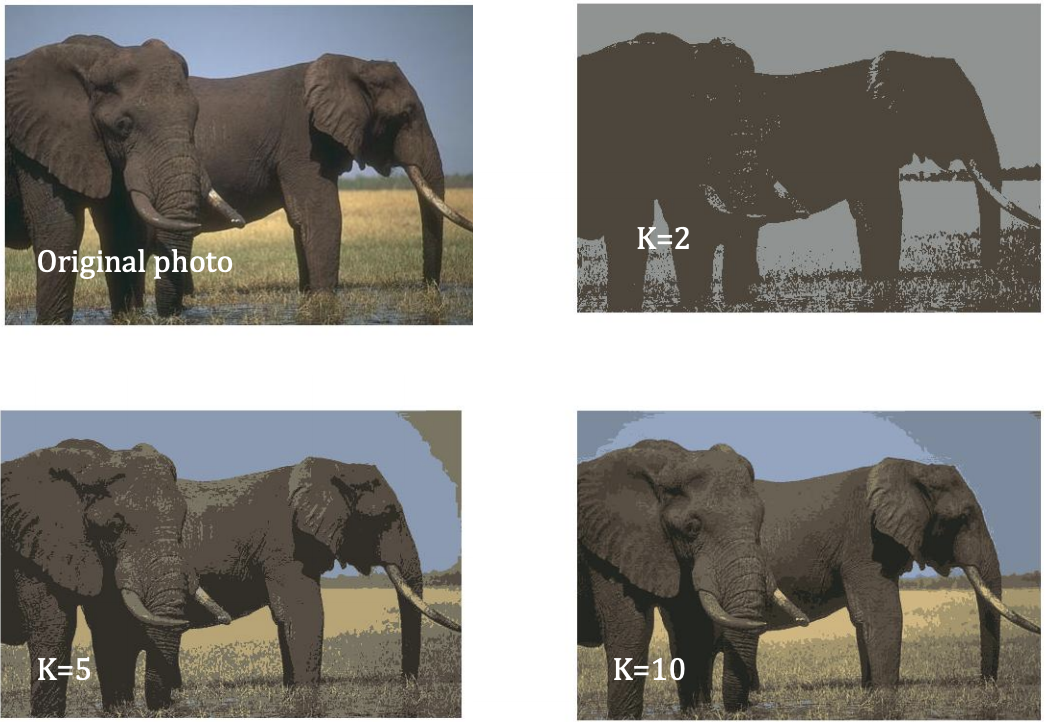

Figure 1. Segmentation of the image into different segments based on K-Means algorithm

## K-Means Implementation

## Step 1: K-Means Algorithm

Write your code in the file "KMeans.m" included in the folder. Your *KMeans*(Image,K,maxIter) function takes in 3 inputs — **1) Image**, to run K-Means segmentation on, **2) K**, denoting the number of segments you wish to classify the pixels of the image image into, **3) maxIter**, specifying the upper bound on the number of iterations before the code terminates. The *KMeans *function should ouput the following — 1) final set of coordinates of the K centroids, 2) final segmented image based on the K centroids. 

[centroid_coord, segmented_image] = KMeans(Image,K,maxIter);

## Step 2: Testing 

Load elephant.jpg and eiffel.jpg images and run K-Means, with K = 2, K = 5 and K = 10 on both the images. Generate ***two*** figures, for elephant and eiffel images, with each figure having 4 subplots with the original image and segmented images (see Fig. 1).

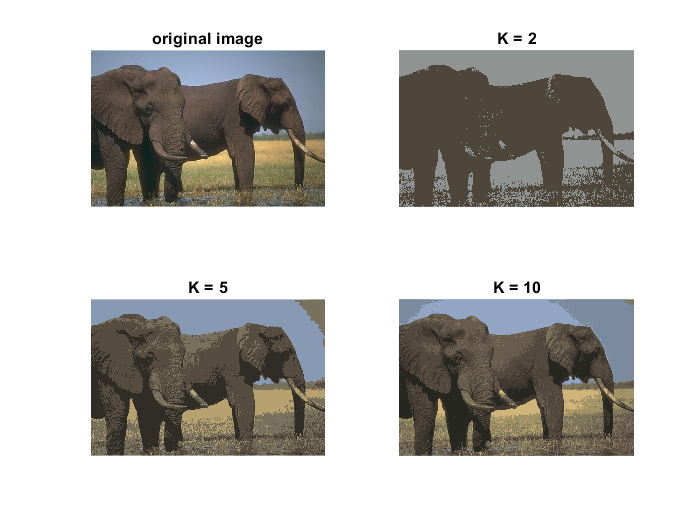

clc
clear
Image = imread('elephant.jpg');
maxIter = 100;
K = [2, 5, 10];
figure()
subplot 221
imshow(Image);
title('original image');
for i =1:length(K)
[centroid_coord, segmented_image] = KMeans(Image,K(i),maxIter);
subplot(2,2,i+1)
imshow(segmented_image)
title(['K = ',num2str(K(i))])
end

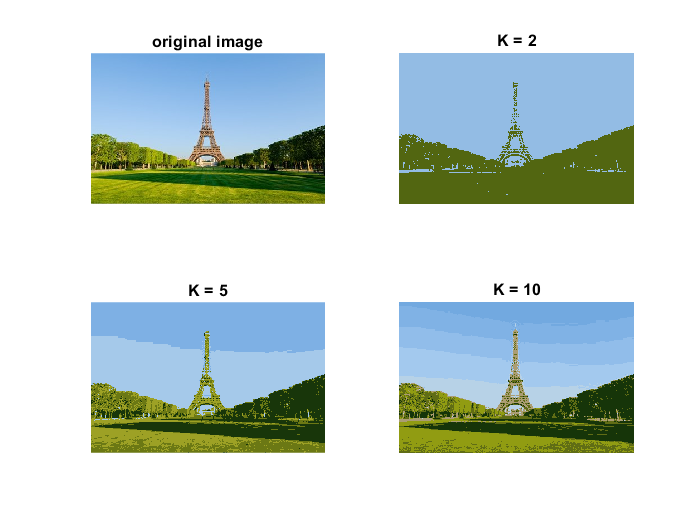


Image = imread('eiffel.jpg');
maxIter = 100;
K = [2, 5, 10];
figure()
subplot 221
imshow(Image);
title('original image');
for i =1:length(K)
[centroid_coord, segmented_image] = KMeans(Image,K(i),maxIter);
subplot(2,2,i+1)
imshow(segmented_image)
title(['K = ',num2str(K(i))])
end

## Step 3: Comparison with MATLAB K-Means

Now use the inbuilt MATLAB *kmeans* function and compare the output for the elephant.jpg image **only.** You code should generate*** one ***figure with the original image, segmented image from your K-Means code with K = 5, segmented image from the MATLAB K-Means function with K = 5.

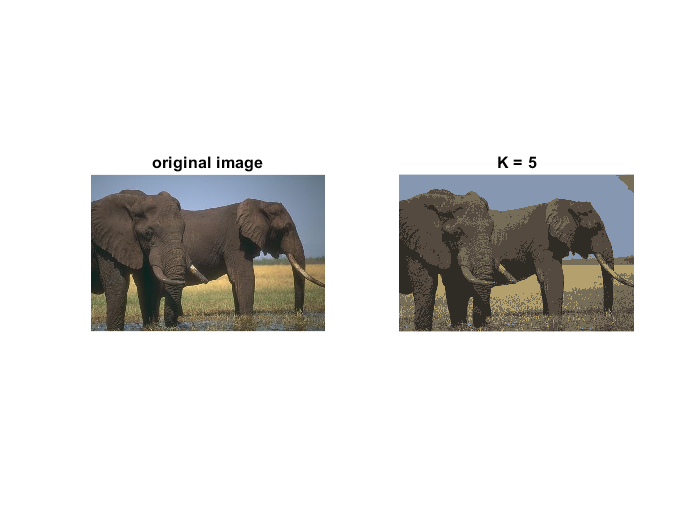

img=imread('elephant.jpg');
figure()
subplot(1,2,1);
imshow(img);
title('original image');
data = double(reshape(img,[],3));
K = 5;
[m n]=kmeans(data,K);
m=reshape(m,size(img,1),size(img,2));
n=n/255;
clusteredImage=label2rgb(m,n);
subplot(1,2,2);
imshow(clusteredImage);
title('K = 5');

## Step 4: Code Optimization (Optional)

Generate the times it takes to run your K-Means and the MATLAB K-Means function with K = 5 on the elephant image. **Print **the runtimes. Try optimizing ***your ***K-Means code to generate the segmented image within the order of a few seconds, in comparison to the MATLAB K-Means computation times.

img=imread('elephant.jpg');
maxIter = 100;
K = 5;

Matlab inbuilt kmeans:

tic
data = double(reshape(img,[],3));
K = 5;
[m n]=kmeans(data,K);
m=reshape(m,size(img,1),size(img,2));
n=n/255;
inbuilt=label2rgb(m,n);
a = toc;

My KMeans:

tic
[centroid_coord, segmented_image] = KMeans(img,K,maxIter);
b = toc;

My kmeans with stopping Criteria

tic
[centroid_coord, speed_segmented_image] = Speed_KMeans(img,K,maxIter);

Stop Iteration: Cluster centroids did not update


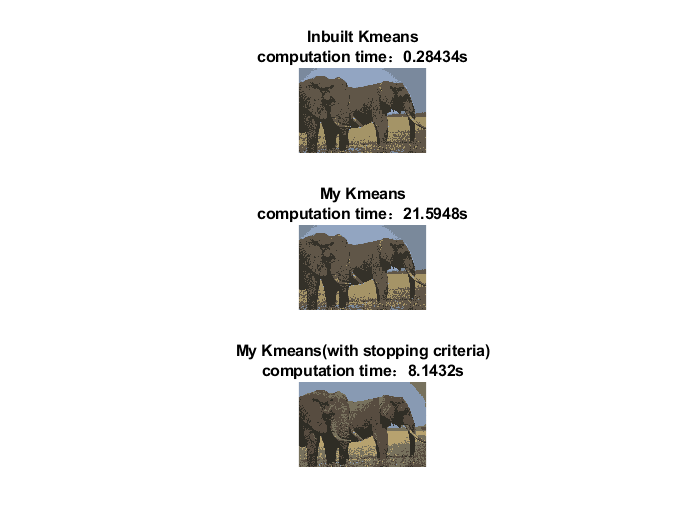

c = toc;
figure()
subplot 311
imshow(inbuilt);
title({['Inbuilt Kmeans'];['computation time：',num2str(a),'s']});
subplot 312
imshow(segmented_image)
title({['My Kmeans'];['computation time：',num2str(b),'s']});
subplot 313
imshow(speed_segmented_image)
title({['My Kmeans(with stopping criteria)'];['computation time：',num2str(c),'s']});